a) Write out the equations of motion for this system, based on the acceleration of the wheelchair and the basic motor model.

b) Either algebraically, symbolically, or numerically solve for the forward displacement of the wheelchair with the following conditions:

Motor: Maxon EC45-Flat 70W 30V, part # 402685 (data sheet attached) Gear ratio: 1:1

Initial Conditions: x = 0, dx/dt = 0

How far did the wheelchair travel? You may use Matlab, Python, or other software. Hint: In Matlab, instructions on solving differential equations symbolically: [https://www.mathworks.com/help/symbolic/solve-a-single-differential-equation.html](https://www.mathworks.com/help/symbolic/solve-a-single-differential-equation.html) and numerically: [https://www.mathworks.com/help/matlab/math/solve-nonstiff-odes.html](https://www.mathworks.com/help/matlab/math/solve-nonstiff-odes.html) 

c) Plot the final displacement for all gear ratios from 1:1 to 100:1. What is the optimal gear ratio?

d) Now consider the motor selection question. Of the four EC45-Flat 70W motors in the attached datasheet, which will move the wheelchair the farthest in 5 seconds? (Pair each motor with its own optimal gear ratio)

Motor Type: 402685

clear all
close all
clc

syms x(t)
dist_list = [];
ratio = [];
Kt = 45.1 * 0.001;
Kv = 212;
Ke = 1/Kv/0.105;
Vs = 30 * 0.84;
R = 1.16;
m = 100;
r = 0.5;
rotor_I = 181;
J = rotor_I * 1e-7 + m * r^2;

for N=1:100
    Dx = diff(x);
    ode = diff(x,t,2) == -(Kt * Ke / ((J/N^2)*R)) * diff(x,t) + (Kt * Vs)/((J/N^2) * R);
    cond1 = x(0) == 0;
    cond2 = Dx(0) == 0;
    conds = [cond1 cond2];
    xSol(t) = dsolve(ode,conds);
    xSol = simplify(xSol);
    dist = double(subs(xSol, t, 5));
    dist_list(N) = dist * r * 1/N;
    ratio(N) = N;
end

[dist_max, index] = max(dist_list);
N_opt = ratio(index)
dist_max

figure
plot(ratio, dist_list)

Motor Type: 397172

clear all
close all
clc

syms x(t)
dist_list = [];
ratio = [];
Kt = 36.9 * 0.001;
Kv = 259;
Ke = 1/Kv/0.105;
Vs = 24 * 0.85;
R = 0.608;
m = 100;
r = 0.5;
rotor_I = 181;
J = rotor_I * 1e-7 + m * r^2;

for N=1:100
    Dx = diff(x);
    ode = diff(x,t,2) == -(Kt * Ke / ((J/N^2)*R)) * diff(x,t) + (Kt * Vs)/((J/N^2) * R);
    cond1 = x(0) == 0;
    cond2 = Dx(0) == 0;
    conds = [cond1 cond2];
    xSol(t) = dsolve(ode,conds);
    xSol = simplify(xSol);
    dist = double(subs(xSol, t, 5));
    dist_list(N) = dist * r * 1/N;
    ratio(N) = N;
end

[dist_max, index] = max(dist_list);
N_opt = ratio(index)

N_opt = 69

dist_max

dist_max = 11.7713

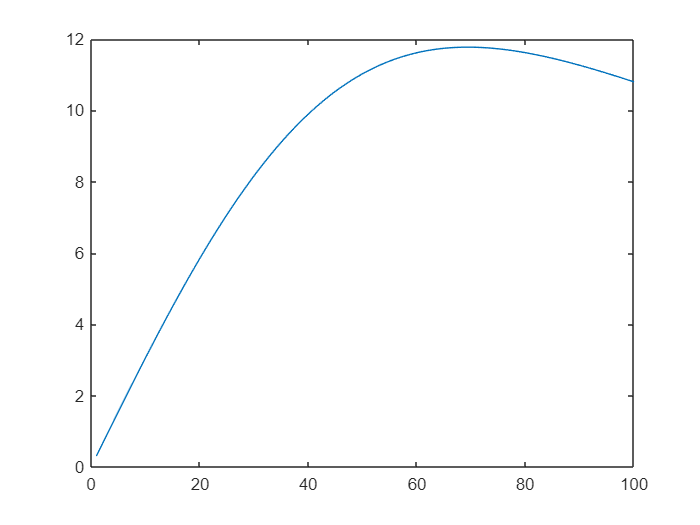


figure
plot(ratio, dist_list)

Motor Type: 402686

clear all
close all
clc

syms x(t)
dist_list = [];
ratio = [];
Kt = 53.3 * 0.001;
Kv = 179;
Ke = 1/Kv/0.105;
Vs = 36 * 0.83;
R = 1.74;
m = 100;
r = 0.5;
rotor_I = 181;
J = rotor_I * 1e-7 + m * r^2;

for N=1:100
    Dx = diff(x);
    ode = diff(x,t,2) == -(Kt * Ke / ((J/N^2)*R)) * diff(x,t) + (Kt * Vs)/((J/N^2) * R);
    cond1 = x(0) == 0;
    cond2 = Dx(0) == 0;
    conds = [cond1 cond2];
    xSol(t) = dsolve(ode,conds);
    xSol = simplify(xSol);
    dist = double(subs(xSol, t, 5));
    dist_list(N) = dist * r * 1/N;
    ratio(N) = N;
end

[dist_max, index] = max(dist_list);
N_opt = ratio(index)

N_opt = 81

dist_max

dist_max = 10.1832

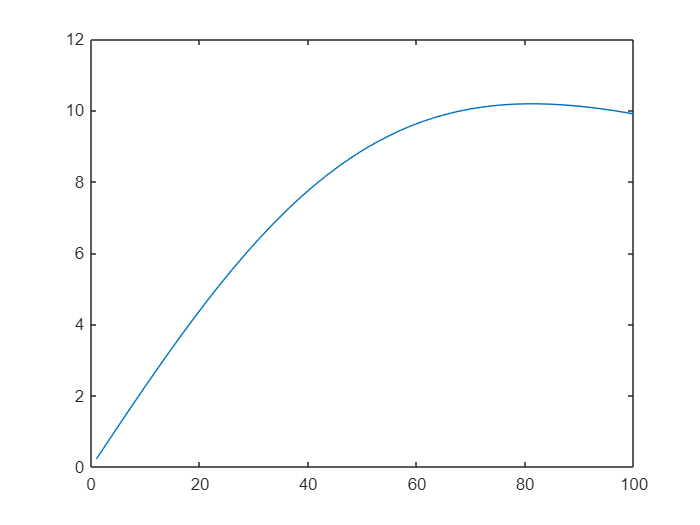


figure
plot(ratio, dist_list)

Motor Type: 402687

clear all
close all
clc

syms x(t)
dist_list = [];
ratio = [];
Kt = 131 * 0.001;
Kv = 72.7;
Ke = 1/Kv/0.105;
Vs = 48 * 0.84;
R = 6.89;
m = 100;
r = 0.5;
rotor_I = 181;
J = rotor_I * 1e-7 + m * r^2;

for N=1:100
    Dx = diff(x);
    ode = diff(x,t,2) == -(Kt * Ke / ((J/N^2)*R)) * diff(x,t) + (Kt * Vs)/((J/N^2) * R);
    cond1 = x(0) == 0;
    cond2 = Dx(0) == 0;
    conds = [cond1 cond2];
    xSol(t) = dsolve(ode,conds);
    xSol = simplify(xSol);
    dist = double(subs(xSol, t, 5));
    dist_list(N) = dist * r * 1/N;
    ratio(N) = N;
end

[dist_max, index] = max(dist_list);
N_opt = ratio(index)

N_opt = 66

dist_max

dist_max = 6.8992

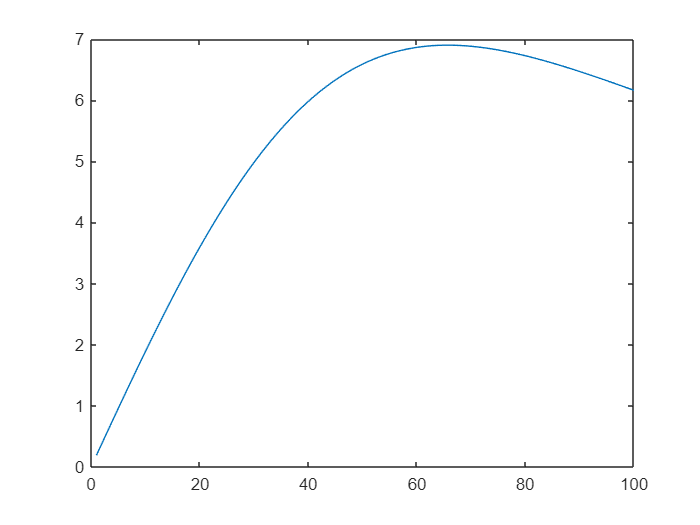


figure
plot(ratio, dist_list)

(e) Gears only come in certain ratios. Based on the options for GP 42 C gearboxes in the attached datasheet, what is the optimal motor+gearbox combination?

Motor Type: 391712

close all
clear all
clc

syms x(t)
dist_list = [];
Kt = 36.9 * 0.001;
Kv = 259;
Ke = 1/Kv/0.105;
Vs = 24 * 0.85;
R = 0.608;
m = 100;
r = 0.5;
rotor_I = 181;
J = rotor_I * 1e-7 + m * r^2;
N_list = [3.5 4.3 6 12 15 19 21 26 36 43 53 66 74 81 91]; 

for i = 1:length(N_list)
    Dx = diff(x);
    ode = diff(x,t,2) == -(Kt * Ke / ((J/N_list(i)^2)*R)) * diff(x,t) + (Kt * Vs)/((J/N_list(i)^2) * R);
    cond1 = x(0) == 0;
    cond2 = Dx(0) == 0;
    conds = [cond1 cond2];
    xSol(t) = dsolve(ode,conds);
    xSol = simplify(xSol);
    dist = double(subs(xSol, t, 5));
    dist_list(i) = dist * r * 1/N_list(i);
end

[dist_max, index] = max(dist_list);
N_opt = N_list(index)

N_opt = 66

dist_max

dist_max = 11.7525

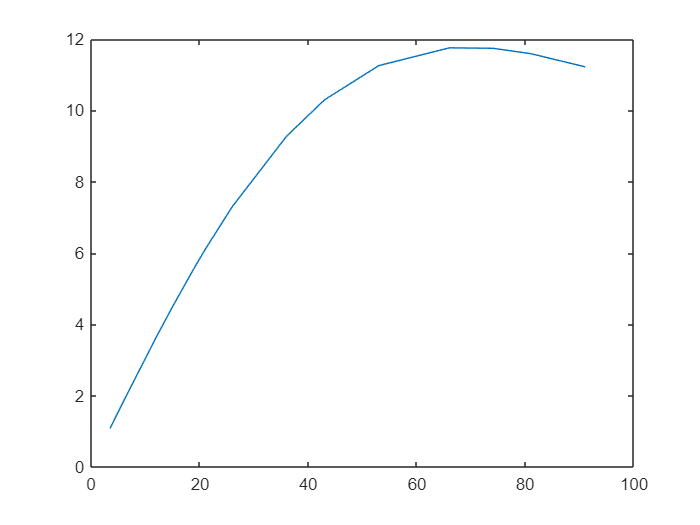


figure
plot(N_list, dist_list)  

Motor Type: 402685

close all
clear all
clc

syms x(t)
dist_list = [];
Kt = 45.1 * 0.001;
Kv = 212;
Ke = 1/Kv/0.105;
Vs = 30 * 0.84;
R = 1.16;
m = 100;
r = 0.5;
rotor_I = 181;
J = rotor_I * 1e-7 + m * r^2;
N_list = [3.5 4.3 6 12 15 19 21 26 36 43 53 66 74 81 91]; 

for i = 1:length(N_list)
    Dx = diff(x);
    ode = diff(x,t,2) == -(Kt * Ke / ((J/N_list(i)^2)*R)) * diff(x,t) + (Kt * Vs)/((J/N_list(i)^2) * R);
    cond1 = x(0) == 0;
    cond2 = Dx(0) == 0;
    conds = [cond1 cond2];
    xSol(t) = dsolve(ode,conds);
    xSol = simplify(xSol);
    dist = double(subs(xSol, t, 5));
    dist_list(i) = dist * r * 1/N_list(i);
end

[dist_max, index] = max(dist_list);
N_opt = N_list(index)

N_opt = 81

dist_max

dist_max = 10.5227

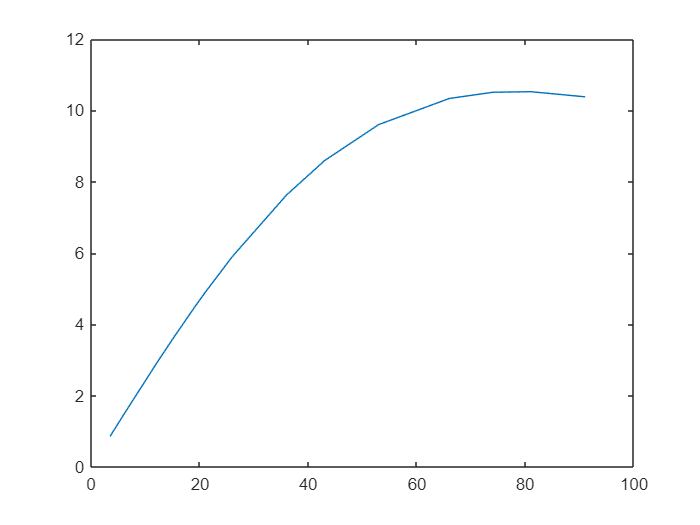


figure
plot(N_list, dist_list)

Motor Type: 402686

close all
clear all
clc

syms x(t)
dist_list = [];
Kt = 53.3 * 0.001;
Kv = 179;
Ke = 1/Kv/0.105;
Vs = 36 * 0.83;
R = 1.74;
m = 100;
r = 0.5;
rotor_I = 181;
J = rotor_I * 1e-7 + m * r^2;
N_list = [3.5 4.3 6 12 15 19 21 26 36 43 53 66 74 81 91]; 

for i = 1:length(N_list)
    Dx = diff(x);
    ode = diff(x,t,2) == -(Kt * Ke / ((J/N_list(i)^2)*R)) * diff(x,t) + (Kt * Vs)/((J/N_list(i)^2) * R);
    cond1 = x(0) == 0;
    cond2 = Dx(0) == 0;
    conds = [cond1 cond2];
    xSol(t) = dsolve(ode,conds);
    xSol = simplify(xSol);
    dist = double(subs(xSol, t, 5));
    dist_list(i) = dist * r * 1/N_list(i);
end

[dist_max, index] = max(dist_list);
N_opt = N_list(index)

N_opt = 81

dist_max

dist_max = 10.1832

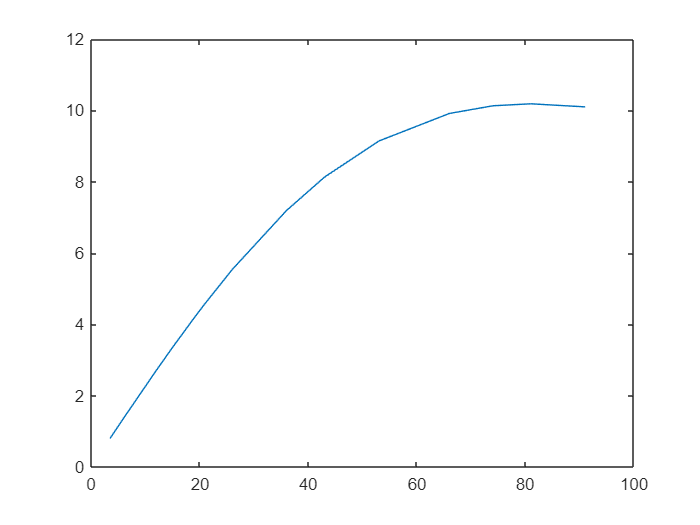


figure
plot(N_list, dist_list)   

Motor Type: 402687

close all
clear all
clc

syms x(t)
dist_list = [];
Kt = 131 * 0.001;
Kv = 72.7;
Ke = 1/Kv/0.105;
Vs = 48 * 0.84;
R = 6.89;
m = 100;
r = 0.5;
rotor_I = 181;
J = rotor_I * 1e-7 + m * r^2;
N_list = [3.5 4.3 6 12 15 19 21 26 36 43 53 66 74 81 91]; 

for i = 1:length(N_list)
    Dx = diff(x);
    ode = diff(x,t,2) == -(Kt * Ke / ((J/N_list(i)^2)*R)) * diff(x,t) + (Kt * Vs)/((J/N_list(i)^2) * R);
    cond1 = x(0) == 0;
    cond2 = Dx(0) == 0;
    conds = [cond1 cond2];
    xSol(t) = dsolve(ode,conds);
    xSol = simplify(xSol);
    dist = double(subs(xSol, t, 5));
    dist_list(i) = dist * r * 1/N_list(i);
end

[dist_max, index] = max(dist_list);
N_opt = N_list(index)

N_opt = 66

dist_max

dist_max = 6.8992

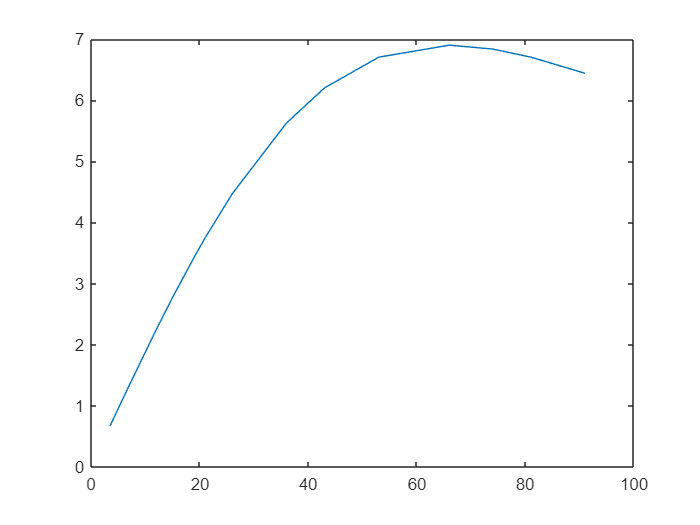


figure
plot(N_list, dist_list)